# 探究广深两地的综合发展动力

## 第一章　研究问题

- 广深两地与其他城市相比，具有哪些方面的优势？（简单比较）

- 在人口就业、房地产、财政金融、贸易经济、卫生教育、开发区建设共6个指标中，哪些指标与关乎着当地的国内生产总值？（主成分分析）

- 2020年～2025年，广深两地的7个指标又会有什么变化？（曲线拟合）

## 第二章　研究方法

### 简单比较

% 读取数据源（20年全国主要城市国内生产总值）
data = readtable("data\NEA\20_Major_GDP.xls", "Range", "A4:U40");

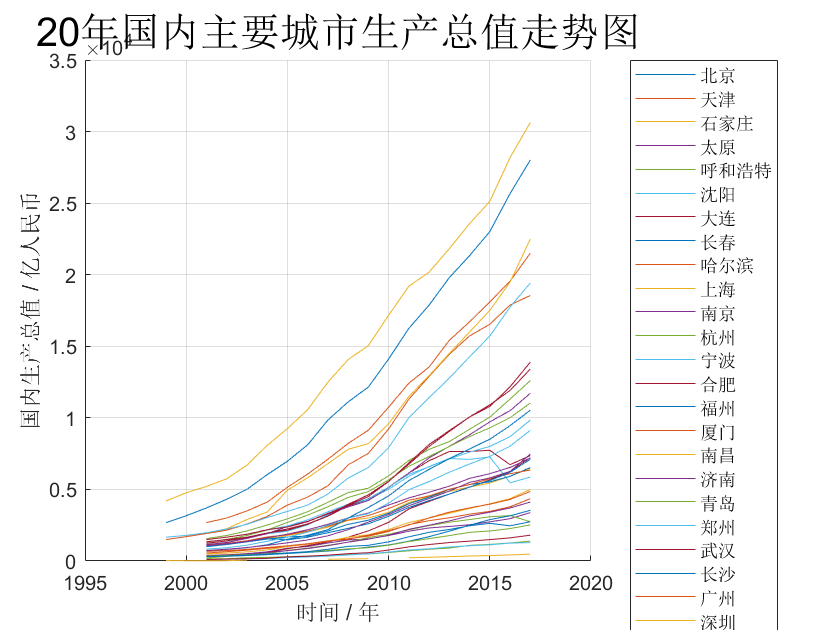

figure();
hold on
for i = 1 : height(data)
    plot( ...
        2018 : -1 : 1999, ...
        data{i, 2 : width(data)}, ...
        "DisplayName", ...
        data{i, 1}{:} ...
    );
end
xlabel("时间 / 年");
ylabel("国内生产总值 / 亿人民币");
legend("show", "Location", "bestoutside");
title("20年国内主要城市生产总值走势图", "FontSize", 20);
hold off
grid on

% 读取数据（20年深圳全数据）
data = readtable("data\NEA\20_Shenzhen_All.xls", "Range", "A4:U8");

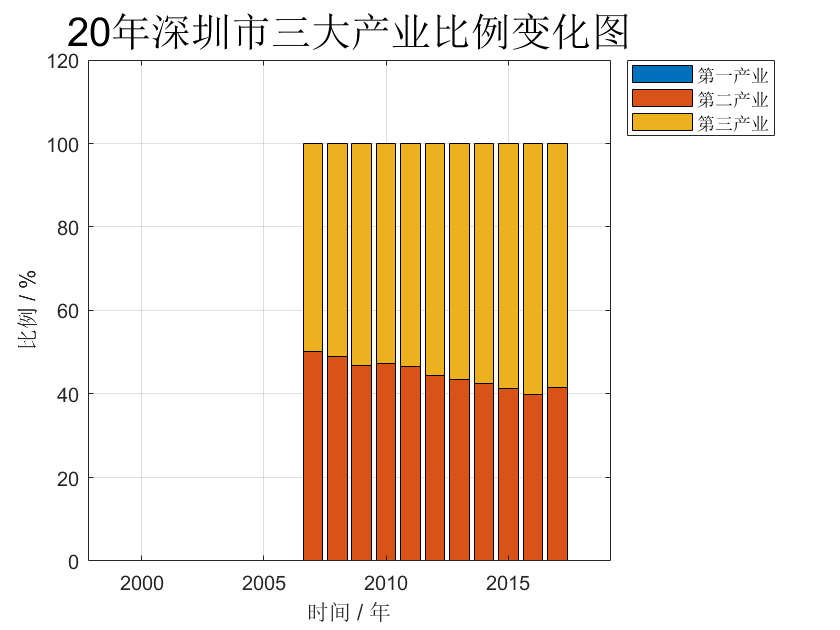

figure();
% 数据变换
data = table2array(data(2 : height(data), 2 : width(data)))';
% 三大产业总生产值
total = sum(data, 2);
% 绘制比例堆叠图
bar((2018 : -1 : 1999)', data ./ total * 100, "stacked");
xlabel("时间 / 年");
ylabel("比例 / %");
legend("第一产业", "第二产业", "第三产业", "Location", "bestoutside");
title("20年深圳市三大产业比例变化图", "FontSize", 20);
grid on